% Define robot parameters
% link dimensions in m
L1 = 500 * 10^-3;
L2 = 250 * 10^-3;
L3 = 770 * 10^-3;
L4 = 70 * 10^-3;
L5 = 780 * 10^-3;
L6 = 215 * 10^-3;

% initial joint angles
th_list = [0 -120 90 0 -90 0] * pi/180;   % Convert to radians

% target joint angles
th_list_2 = [45 -90 15 30 -60 45] * pi/180;

% home configuration
M = [
    1, 0, 0, L2+L3+L5+L6;
    0, 1, 0, 0;
    0, 0, 1, -L4;
    0, 0, 0, 1];

% axes of rotation
w1 = [0; 0; -1];
w2 = [0; 1; 0];
w3 = [0; 1; 0];
w4 = [-1; 0; 0];
w5 = [0; 0; 1];
w6 = [-1; 0; 0];
w_list = [w1, w2, w3, w4, w5, w6];

% screw axis position vectors, space frame
q1 = [0; 0; -L1];
q2 = [L2; 0; 0];
q3 = [L2+L3; 0; 0];
q4 = [L2+L3; 0; -L4];
q5 = [L2+L3+L5; 0; -L4];
q6 = [L2+L3+L5+L6; 0; -L4];
q_list = [q1, q2, q3, q4, q5, q6];

% velocity vectors
v_list = zeros([3, length(w_list)]);    % list of velocity vectors
% compute cross products of w and q. Add them to v_list
for i = 1:length(w_list)
    v = cross(-w_list(:, i), q_list(:, i));  % compute the cross product
    v_list(:, i) = v;   % add velocity vector element to v_list
end

% compute spatial screw list
screw_list = zeros([6, length(w_list)]);    % list of screws
% format the screw axes using w and v. Add them to screw_list
for i = 1:length(w_list)
    screw = [w_list(:, i ); v_list(:, i)];  % stack w(i) and v(i)
    screw_list(:, i) = screw;   % add screw axis to screw_list
end

% transform screw list to body frame
adj_M_inv = adj_transform(inv(M));      % adjacent of home configuration
body_screw_list = adj_M_inv * screw_list;       % transforms screw axis to body frame

% transform q's to body frame
q_list_h = [q_list; ones(1, length(q_list))];  % homogeneous form
body_q_list_h = inv(M) * q_list_h;  % T_bs * q_s = q_b
body_q_list = body_q_list_h(1:3, :);

Compute Inverse Kinematics

T_d = FK_space(M, screw_list, th_list_2, q_list, false);  % Desired config

% Numerical algorithm
[th_d_NA, thVelList] = J_inverse_kinematics(M, body_screw_list, th_list, body_q_list, T_d);

% Jacobian transpose
th_d_JT = J_transpose_kinematics(M, body_screw_list, th_list, body_q_list, T_d);

Plot Robot Motion - Numerical

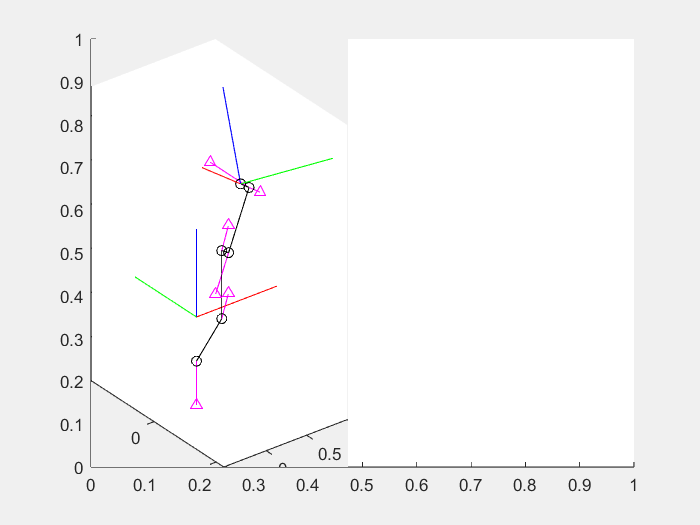

loops = 100;
fig = figure;
Mov(loops) = struct('cdata',[],'colormap',[]);
fig.Visible = 'off';

FK_space(M, screw_list, th_list, q_list, true);
drawnow
Mov(1) = getframe;
clf

FK_space(M, screw_list, th_list_2, q_list, true);
drawnow
Mov(2) = getframe;
clf

fig.Visible = 'on';
movie(Mov, 2, 1);

Plot Robot Motion - Jacobian Transpose